%calculating the mean first passage time analytically/numerically 
%to investigate optimal position of 1 mismatch from perspective of RNA/DNA
%toehold exchange including spontaneous incumbent and invader dissociation

b = 20 %define branch migration domain length

b = 20

g = 5 %define invader toehold length 

g = 5

g2 = 6 %define incumbent toehold length 

g2 = 6


bg2 = b + g2 %define branch migration domain + incumbent toehold length 

bg2 = 26


R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGrd = -0.4*R*temp

dGrd = -0.2370

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant 
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 20)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch positions 
for m = 1:20
     m
     
     trans_state = (- dGbp  - dGrd)*(b+ g-1)
     react_coord = zeros(1, b-1)
     %loop through states after mismatch and define free energy for invader
     %dissociation 
     for state = 1:b-m
        react_coord(state) = (-dGbp - dGrd)*(state) + dGmm;
     end
     %loop through states before mismatch and define free energy for
     %invader dissocaition 
     for state = b-m+1:b-1
        react_coord(state) = (- dGbp - dGrd)*(state)
     end

     %define forward and reverse transition rates 
     k_AA = 0;
     k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
     k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
     k_BC1ij = k_bp;
     k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp));
     k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp));
     k_Cf = k_bp * exp(-dGbm/(R*temp));
     k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp));
     k_Crm = k_bp* exp((dGmm - dGbm + dGrd)/(R*temp)); %I have added + dGrd
     k_Crm_end = k_bp * exp((dGmm - dGbm - dGp + dGrd)/(R*temp)); %I have added + dGrd
     k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
     k_DEij = k_bp * exp(dGbp/(R*temp));
     k_DEji = k_bp;
     k_EF = k_bp*exp(dGbp/(R*temp));
     k_FE = 0
     k_FF = 1    
    
     %create arrays of forward and reverse transition rates for
     %mismatch-free system
     Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
     Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        
     %define spontaneous invader dissociation rates for mismatch-free
     %system
     Koff_inv_perf = [repmat(0, [1, g2+1])];
     for n = b+g-1:-1:g+1
        Koff_inv_perf = horzcat(Koff_inv_perf, [k_bp*exp(-(n*(-dGbp-dGrd))/(R*temp))]);
     end
     Koff_inv_perf = horzcat(Koff_inv_perf, [repmat(0, [1, g+1])]);  
     %Koff_inv_perf = [repmat(0, [1, b+g + g2+1])];
    
     if m == b
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(g2 + b - m + 1) = k_Crm_end
        
        %define spontaneous incumbent dissociation rates 
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2+ 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
        %define spontaneous invader dissociation rates for mismatch system
        Koff_inv = [repmat(0, [1, g2+1])];
        for n = 1:b-1
            Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(-dGbp-dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff_inv = horzcat(Koff_inv, [repmat(0, [1, g+1])]);
        %Koff_inv = [repmat(0, [1, b+g + g2+1])];
        
     else
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(g2 + b - m + 1) = k_Crm
        
        %define spontaneous incumbent dissociation rates 
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2+ 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
        %define spontaneous invader dissociation rates for mismatch system 
        Koff_inv = [repmat(0, [1, g2+1])];
        for n = 1:b-1
            Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(-dGbp-dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff_inv = horzcat(Koff_inv, [repmat(0, [1, g+1])])
        
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    j_cycle = zeros(1,numel(Kf));
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + (Koff(Pn) + Koff_inv(Pn)) * Pn_jN_1(Pn)
        j_cycle(Pn) = Pn_jN_1(Pn)*Koff_inv(Pn);
    end
        
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    j_cycle_perf = zeros(1,numel(Kf_perf));
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + (Koff(Pn) + Koff_inv_perf(Pn)) * Pn_jN_1_perf(Pn);
        j_cycle_perf(Pn) = Pn_jN_1_perf(Pn)*Koff_inv_perf(Pn);
    end
   
    j_disp = jn_jN_1(end-1) - sum(j_cycle(1:end)) %successful flux for mismatch system
    first_pass_time (m) = (1/j_disp)*sum(Pn_jN_1) %first passage time for mismatch system
    %first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1)
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8)) %effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1) %prob of being in unbound state for mismatch system
    
    j_disp_perf = jn_jN_1_perf(end-1) - sum(j_cycle_perf(1:end)) %successful flux for mismatch-free system
    first_pass_time_perf (m) = (1/j_disp_perf)*sum(Pn_jN_1_perf) %first passage time for mismatch-free system
    %first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) 
    k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8)) %effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf) %prob of being in unbound state for  mismatch-free system
    
end

m = 1

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912    0.2912         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912    0.2912         0


Kb = 	1.0e+08 *

         0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0291    0.0291    0.0291    0.0291    0.0291         0


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv = 	1.0e+04 *

         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0052    0.0958    1.7756         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.8013         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.8013    2.8013         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.8013    2.8013    2.8013         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.8013    2.8013    2.8013    2.8013         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.8013    2.8013    2.8013    2.8013    2.8013         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.8013    2.8013    2.8013    2.8013    2.8013    2.8013         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.8013    2.8013    2.8013    2.8013    2.8013    2.8013    2.8013


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time = 	1.0e+03 *

    3.9083         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    5.1173         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 2

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   33.3061   35.0360   36.7658   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0081    0.1502    2.7857   51.6502  957.6617    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.2114         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.2114    2.2114         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.2114    2.2114    2.2114         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.2114    2.2114    2.2114    2.2114         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.2114    2.2114    2.2114    2.2114    2.2114


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.2114    2.2114    2.2114    2.2114    2.2114


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0966    2.2114    2.2114    2.2114    2.2114    2.2114


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     5.1173    7.8158         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 3

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   33.3061   35.0360   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   33.3061   35.0360   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0081    0.1502    2.7857   51.6502    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0674         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0674    1.8192         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0674    1.8192    1.8192         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0674    1.8192    1.8192    1.8192         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0674    1.8192    1.8192    1.8192    1.8192         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0674    1.8192    1.8192    1.8192    1.8192    1.8192


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0674    1.8192    1.8192    1.8192    1.8192    1.8192


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0069    1.0674    1.8192    1.8192    1.8192    1.8192    1.8192


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5117    0.7816    1.1573         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 4

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   33.3061   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   33.3061   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   33.3061   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0081    0.1502    2.7857    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0053         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0053    1.0463         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0053    1.0463    1.5559         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0053    1.0463    1.5559    1.5559         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0053    1.0463    1.5559    1.5559    1.5559         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0053    1.0463    1.5559    1.5559    1.5559    1.5559         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0053    1.0463    1.5559    1.5559    1.5559    1.5559    1.5559


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0053    1.0463    1.5559    1.5559    1.5559    1.5559    1.5559


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0053    1.0463    1.5559    1.5559    1.5559    1.5559    1.5559


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5117    0.7816    1.1573    1.7034         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 5

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   31.5762   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0081    0.1502    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0042         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0042    1.0321         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0042    1.0321    1.3794         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0042    1.0321    1.3794    1.3794         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0042    1.0321    1.3794    1.3794    1.3794         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0042    1.0321    1.3794    1.3794    1.3794    1.3794         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0042    1.0321    1.3794    1.3794    1.3794    1.3794    1.3794


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0042    1.0321    1.3794    1.3794    1.3794    1.3794    1.3794


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0042    1.0321    1.3794    1.3794    1.3794    1.3794    1.3794


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5117    0.7816    1.1573    1.7034    2.4913         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 6

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   29.8463   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0081    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019    1.0034         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019    1.0034    1.0226         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019    1.0034    1.0226    1.2611         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019    1.0034    1.0226    1.2611    1.2611         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019    1.0034    1.0226    1.2611    1.2611    1.2611         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019    1.0034    1.0226    1.2611    1.2611    1.2611    1.2611         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019    1.0034    1.0226    1.2611    1.2611    1.2611    1.2611    1.2611


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019    1.0034    1.0226    1.2611    1.2611    1.2611    1.2611    1.2611


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0019    1.0034    1.0226    1.2611    1.2611    1.2611    1.2611    1.2611


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5117    0.7816    1.1573    1.7034    2.4913    3.6104         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873         0         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 7

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   28.1164   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0029         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0029    1.0162         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0029    1.0162    1.1818         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0029    1.0162    1.1818    1.1818         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0029    1.0162    1.1818    1.1818    1.1818         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0029    1.0162    1.1818    1.1818    1.1818    1.1818         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0029    1.0162    1.1818    1.1818    1.1818    1.1818    1.1818


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0029    1.0162    1.1818    1.1818    1.1818    1.1818    1.1818


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0029    1.0162    1.1818    1.1818    1.1818    1.1818    1.1818


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5117    0.7816    1.1573    1.7034    2.4913    3.6104    5.1655         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849         0         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0         0         0         0         0         0


m = 8

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   26.3866   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0026         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0026    1.0119         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0026    1.0119    1.1287         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0026    1.0119    1.1287    1.1287         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0026    1.0119    1.1287    1.1287    1.1287         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0026    1.0119    1.1287    1.1287    1.1287    1.1287         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0026    1.0119    1.1287    1.1287    1.1287    1.1287    1.1287


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0026    1.0119    1.1287    1.1287    1.1287    1.1287    1.1287


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0026    1.0119    1.1287    1.1287    1.1287    1.1287    1.1287


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5117    0.7816    1.1573    1.7034    2.4913    3.6104    5.1655    7.2600         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814         0         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0         0         0         0         0


m = 9

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   24.6567   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0023         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0023    1.0091         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0023    1.0091    1.0930         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0023    1.0091    1.0930    1.0930         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0023    1.0091    1.0930    1.0930    1.0930         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0023    1.0091    1.0930    1.0930    1.0930    1.0930         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0023    1.0091    1.0930    1.0930    1.0930    1.0930    1.0930


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0023    1.0091    1.0930    1.0930    1.0930    1.0930    1.0930


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0023    1.0091    1.0930    1.0930    1.0930    1.0930    1.0930


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5117    0.7816    1.1573    1.7034    2.4913    3.6104    5.1655    7.2600    9.9641         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764         0         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0         0         0         0


m = 10

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   22.9268   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0022         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0022    1.0072         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0022    1.0072    1.0691         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0022    1.0072    1.0691    1.0691         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0022    1.0072    1.0691    1.0691    1.0691         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0022    1.0072    1.0691    1.0691    1.0691    1.0691         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0022    1.0072    1.0691    1.0691    1.0691    1.0691    1.0691


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0022    1.0072    1.0691    1.0691    1.0691    1.0691    1.0691


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0022    1.0072    1.0691    1.0691    1.0691    1.0691    1.0691


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691         0         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0         0         0


m = 11

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   21.1969   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0021         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0021    1.0059         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0021    1.0059    1.0531         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0021    1.0059    1.0531    1.0531         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0021    1.0059    1.0531    1.0531    1.0531         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0021    1.0059    1.0531    1.0531    1.0531    1.0531         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0021    1.0059    1.0531    1.0531    1.0531    1.0531    1.0531


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0021    1.0059    1.0531    1.0531    1.0531    1.0531    1.0531


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0021    1.0059    1.0531    1.0531    1.0531    1.0531    1.0531


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176         0         0         0         0         0         0         0         0         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264    1.7012         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586         0         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0         0


m = 12

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   19.4671   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0050         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0050    1.0424         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0050    1.0424    1.0424         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0050    1.0424    1.0424    1.0424         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0050    1.0424    1.0424    1.0424    1.0424         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0050    1.0424    1.0424    1.0424    1.0424    1.0424


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0050    1.0424    1.0424    1.0424    1.0424    1.0424


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0050    1.0424    1.0424    1.0424    1.0424    1.0424


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176    0.0957         0         0         0         0         0         0         0         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264    1.7012    2.0901         0         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586    0.9436         0         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0         0


m = 13

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   17.7372   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0044         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0044    1.0352         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0044    1.0352    1.0352         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0044    1.0352    1.0352    1.0352         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0044    1.0352    1.0352    1.0352    1.0352         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0044    1.0352    1.0352    1.0352    1.0352    1.0352


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0044    1.0352    1.0352    1.0352    1.0352    1.0352


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0020    1.0044    1.0352    1.0352    1.0352    1.0352    1.0352


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176    0.0957    0.0816         0         0         0         0         0         0         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264    1.7012    2.0901    2.4508         0         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586    0.9436    0.9225         0         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0         0


m = 14

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   16.0073   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0040         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0040    1.0304         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0040    1.0304    1.0304         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0040    1.0304    1.0304    1.0304         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0040    1.0304    1.0304    1.0304    1.0304         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0040    1.0304    1.0304    1.0304    1.0304    1.0304


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0040    1.0304    1.0304    1.0304    1.0304    1.0304


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0040    1.0304    1.0304    1.0304    1.0304    1.0304


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176    0.0957    0.0816    0.0730         0         0         0         0         0         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264    1.7012    2.0901    2.4508    2.7387         0         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586    0.9436    0.9225    0.8929         0         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0         0


m = 15

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475   14.2774   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0038         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0038    1.0272         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0038    1.0272    1.0272         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0038    1.0272    1.0272    1.0272         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0038    1.0272    1.0272    1.0272    1.0272         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0038    1.0272    1.0272    1.0272    1.0272    1.0272


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0038    1.0272    1.0272    1.0272    1.0272    1.0272


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0017    1.0018    1.0019    1.0038    1.0272    1.0272    1.0272    1.0272    1.0272


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0017

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176    0.0957    0.0816    0.0730    0.0686         0         0         0         0         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264    1.7012    2.0901    2.4508    2.7387    2.9168         0         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586    0.9436    0.9225    0.8929    0.8526         0         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0         0


m = 16

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177   12.5475    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0021         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0021    1.0038         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0021    1.0038    1.0252         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0021    1.0038    1.0252    1.0252         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0021    1.0038    1.0252    1.0252    1.0252         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0021    1.0038    1.0252    1.0252    1.0252    1.0252         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0021    1.0038    1.0252    1.0252    1.0252    1.0252    1.0252


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0021    1.0038    1.0252    1.0252    1.0252    1.0252    1.0252


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0017    1.0019    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0020    1.0021    1.0038    1.0252    1.0252    1.0252    1.0252    1.0252


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0020

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176    0.0957    0.0816    0.0730    0.0686    0.0675         0         0         0         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264    1.7012    2.0901    2.4508    2.7387    2.9168    2.9634         0         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586    0.9436    0.9225    0.8929    0.8526    0.7990         0         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0         0


m = 17

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878   10.8177    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878   10.8177    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0058         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0058    1.0074         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0058    1.0074    1.0275         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0058    1.0074    1.0275    1.0275         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0058    1.0074    1.0275    1.0275    1.0275         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0058    1.0074    1.0275    1.0275    1.0275    1.0275         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0058    1.0074    1.0275    1.0275    1.0275    1.0275    1.0275


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0058    1.0074    1.0275    1.0275    1.0275    1.0275    1.0275


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0017    1.0054    1.0056    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0057    1.0058    1.0074    1.0275    1.0275    1.0275    1.0275    1.0275


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0057

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176    0.0957    0.0816    0.0730    0.0686    0.0675    0.0694         0         0         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264    1.7012    2.0901    2.4508    2.7387    2.9168    2.9634    2.8814         0         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586    0.9436    0.9225    0.8929    0.8526    0.7990    0.7309         0         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0         0


m = 18

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    9.0878    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    9.0878    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    0.0002    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0714         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0714    1.0729         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0714    1.0729    1.0920         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0714    1.0729    1.0920    1.0920         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0714    1.0729    1.0920    1.0920    1.0920         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0714    1.0729    1.0920    1.0920    1.0920    1.0920         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0714    1.0729    1.0920    1.0920    1.0920    1.0920    1.0920


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0714    1.0729    1.0920    1.0920    1.0920    1.0920    1.0920


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    1.0017    1.0675    1.0710    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0712    1.0714    1.0729    1.0920    1.0920    1.0920    1.0920    1.0920


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0712

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176    0.0957    0.0816    0.0730    0.0686    0.0675    0.0694    0.0709         0         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264    1.7012    2.0901    2.4508    2.7387    2.9168    2.9634    2.8814    2.8222         0         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586    0.9436    0.9225    0.8929    0.8526    0.7990    0.7309    0.6501         0         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0         0


m = 19

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     7.3579    3.4598         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     7.3579    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    0.5400    0.5400    0.5400    0.5400    0.5400    0.0000    2.9559    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0291    0.0291    0.0291    0.0291


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0039    0.0717    1.3291         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2495         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2495    2.2510         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2495    2.2510    2.2697         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2495    2.2510    2.2697    2.2697         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2495    2.2510    2.2697    2.2697    2.2697         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2495    2.2510    2.2697    2.2697    2.2697    2.2697         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2495    2.2510    2.2697    2.2697    2.2697    2.2697    2.2697


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2495    2.2510    2.2697    2.2697    2.2697    2.2697    2.2697


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0016    2.1821    2.2458    2.2492    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2494    2.2495    2.2510    2.2697    2.2697    2.2697    2.2697    2.2697


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 2.2494

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176    0.0957    0.0816    0.0730    0.0686    0.0675    0.0694    0.0709    0.0413         0


k_eff =     0.0512    0.0782    0.1157    0.1703    0.2491    0.3610    0.5165    0.7260    0.9964    1.3264    1.7012    2.0901    2.4508    2.7387    2.9168    2.9634    2.8814    2.8222    4.8446         0


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586    0.9436    0.9225    0.8929    0.8526    0.7990    0.7309    0.6501    0.5889         0


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776         0


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617         0


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845         0


m = 20

trans_state = 41.5171

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.7299         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689         0         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988         0         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287         0         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585         0         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884         0         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183         0         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482         0         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781         0         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079         0         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378         0


react_coord =     1.7299    3.4598    5.1896    6.9195    8.6494   10.3793   12.1091   13.8390   15.5689   17.2988   19.0287   20.7585   22.4884   24.2183   25.9482   27.6781   29.4079   31.1378   32.8677


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_DC = 604.5562

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb_perf =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.8077    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.2912    0.2912    0.2912    0.2912


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312         0         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312         0         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312         0         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312         0         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312         0         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312         0         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312         0         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312         0         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6313         0         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6313   23.6329         0         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6313   23.6329   23.6538         0         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6313   23.6329   23.6538   23.6538         0         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6313   23.6329   23.6538   23.6538   23.6538         0         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6313   23.6329   23.6538   23.6538   23.6538   23.6538         0


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6313   23.6329   23.6538   23.6538   23.6538   23.6538   23.6538


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6313   23.6329   23.6538   23.6538   23.6538   23.6538   23.6538


jn_jN_1 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   22.4105   23.5653   23.6276   23.6310   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6312   23.6313   23.6329   23.6538   23.6538   23.6538   23.6538   23.6538


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 23.6312

first_pass_time =     3.9083    2.5589    1.7282    1.1741    0.8028    0.5540    0.3872    0.2755    0.2007    0.1508    0.1176    0.0957    0.0816    0.0730    0.0686    0.0675    0.0694    0.0709    0.0413    0.0098


k_eff =     0.0051    0.0078    0.0116    0.0170    0.0249    0.0361    0.0517    0.0726    0.0996    0.1326    0.1701    0.2090    0.2451    0.2739    0.2917    0.2963    0.2881    0.2822    0.4845    2.0466


prob_unbound =     0.9915    0.9912    0.9907    0.9899    0.9889    0.9873    0.9849    0.9814    0.9764    0.9691    0.9586    0.9436    0.9225    0.8929    0.8526    0.7990    0.7309    0.6501    0.5889    0.7592


j_disp_perf = 1.0017

first_pass_time_perf =     5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776    5.7776


k_eff_perf =     3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617    3.4617


prob_unbound_perf =     0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845    0.9845



[val, idx] = max(k_eff(:)) %determine maximum effective rate constant for RNA/DNA direction 

val = 2.0466e+06

idx = 20


ax = gca;
dark_blue = 1/255*[31,120,180];
rred = 1/255*[202,0,32];

plot(1:20, log10(k_eff), 'Color', dark_blue, 'LineWidth', 2)
hold on 
scatter(1:19, log10(k_eff(1:19)), [], dark_blue, 'filled')
ax.LineWidth = 1.5

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [3.5000 6.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [3.5000 6.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [3.5000 6.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


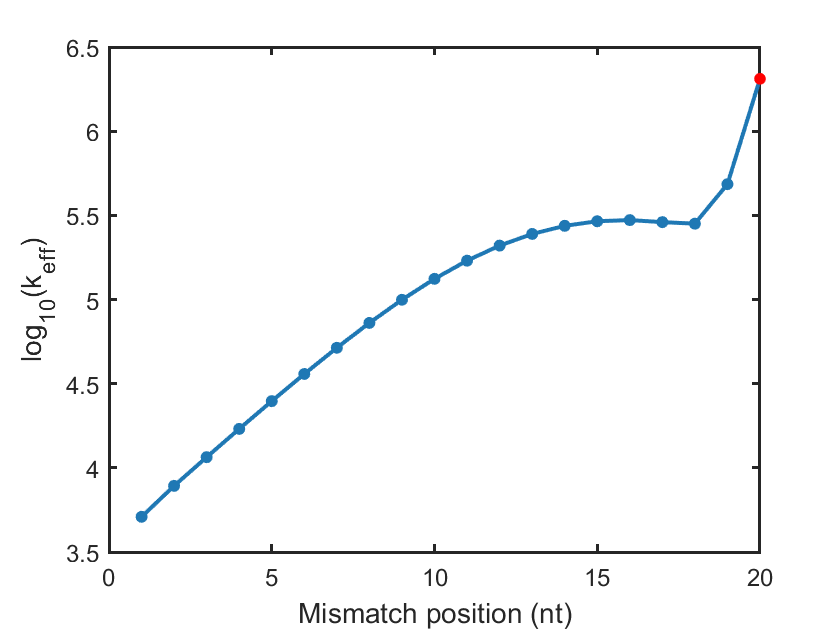

xlabel('Mismatch position (nt)', 'FontSize', 14)
ylabel('log_1_0(k_e_f_f)', 'FontSize', 14)
plot(idx, log10(val), '.r', 'MarkerSize', 20)
hold off 


avr_k_eff = sqrt(k_eff .* flip(DNA_RNA_k_eff)) %determine geometric average of effective rate constant 

avr_k_eff =     0.2224    0.3333    0.4903    0.7157    1.0344    1.4747    2.0640    2.8197    3.7377    4.7799    5.8709    6.9070    7.7767    8.3839    8.6623    8.5815    8.1551    7.5707    8.5335    9.9960


%for RNA/DNA and DNA/RNA directions for mismatch system
avr_k_eff_perf = sqrt(k_eff_perf .* flip(DNA_RNA_k_eff_perf))%determine geometric average of effective rate constant 

avr_k_eff_perf =     8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271    8.2271


%for RNA/DNA and DNA/RNA directions for mismatch-free system
[val, idx] = max(avr_k_eff(:)) %identify maximum average effective rate constant 

val = 9.9960e+05

idx = 20

log10(val)

ans = 5.9998

log10(avr_k_eff(1))

ans = 4.3471


plot(1:20, log10(avr_k_eff), 'Color', dark_blue, 'LineWidth', 2)
hold on
scatter(1:19, log10(avr_k_eff(1:19)), [], dark_blue, 'filled')
ax.LineWidth = 1.5

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [4.2000 6]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [4.2000 6]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 20]
             YLim: [4.2000 6]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


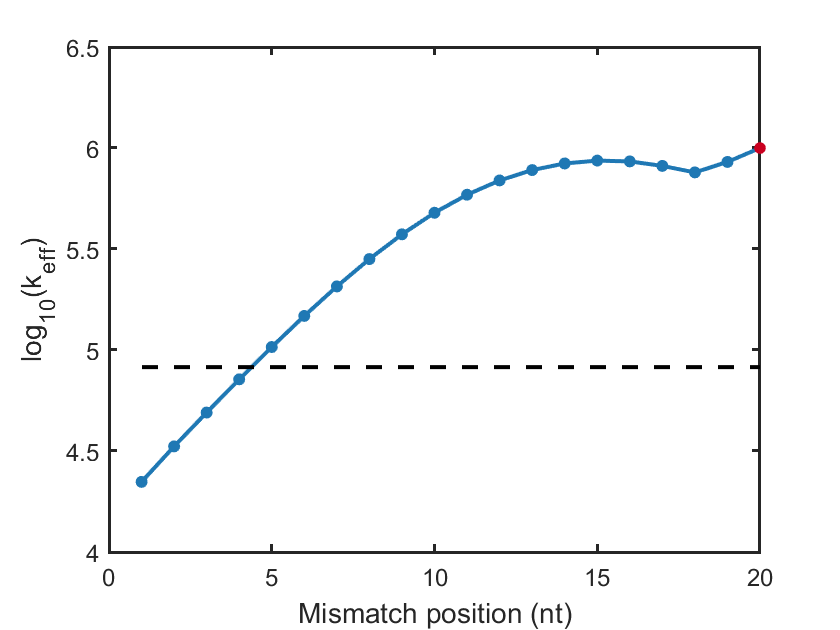

xlabel('Mismatch position (nt)', 'FontSize', 14)
ylabel('log_1_0(k_e_f_f)', 'FontSize', 14)
ylim([4 6.5])
hold on 
plot(idx, log10(val), 'Color', rred,'Marker','.', 'MarkerSize', 20)
plot(1:20, log10(avr_k_eff_perf), 'k--', 'LineWidth', 2)
hold off 